# Fitting the stability-corrected uniform-shear model

This example calls the function fitChougule to estimate the three (or four) parameters of the stability-corrected uniform shear model. The fitting procedure can include "missing information". For example, one may not know everything about the three velocity components or atmospheric stability. Thus, the fitting algorithm attempt to reconstruct the spatial structure of turbulence knowing only a fraction of it. The fitting algorithm is similar as fitMann [1]

[1] E. Cheynet (2022). Fitting the Uniform Shear Model to real data. Zenodo, 2020, doi:10.5281/ZENODO.3774088.

## Definition of the target parameters and model

clearvars;close all;clc;
zeta = 0.6; % non dimensional stability parameter z0 = z/L
GAMMA = 3.2; % Shear parameter
L = 10; % m turbulence length scale
alphaEps =0.05; % m^(4/3)/s^2

% frequency steps
N1 = 30; % number of frequency steps
myIter = 10; % Number of iterationto solve the RDT equations
tic
[PHI,k11,k2_log,k3_log] = ChouguleTurb(alphaEps,GAMMA,L,zeta,'N1',N1,'Niter',myIter);
FM0= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));
Su_Ch= FM0(end-N1+1:end,1,1)';
Sv_Ch= FM0(end-N1+1:end,2,2)';
Sw_Ch= FM0(end-N1+1:end,3,3)';
Suw_Ch= FM0(end-N1+1:end,1,3)';
k11_Ch = k11;
toc

Elapsed time is 29.559100 seconds.


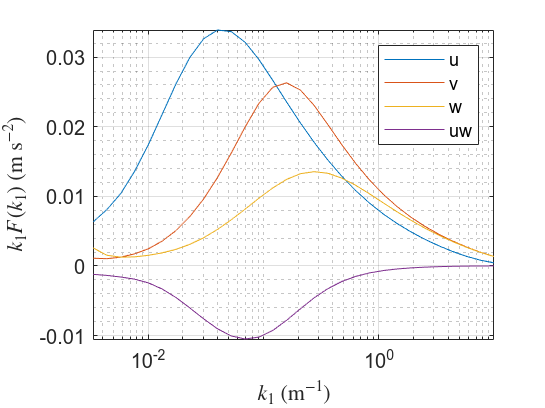


% Plot the target spectra and cross-spectra
clf;close all;
figure
semilogx(k11,k11.*Su_Ch);
set(gca,'yscale','lin')
hold on
semilogx(k11,k11.*Sv_Ch);
semilogx(k11,k11.*Sw_Ch);
semilogx(k11,k11.*Suw_Ch);
xlabel('$k_1$ (m$^{-1}$)','interpreter','latex')
ylabel('$k_1 F(k_1) $ (m s$^{-2}$)','interpreter','latex')
axis tight
set(gcf,'color','w')
axis tight
grid on
grid minor
legend('u','v','w','uw')

## Case 1: The stability parameter $\zeta$is unknown

In this example, we assume that the three velocity components are known, but not the Obukhov length. The fitting procedure will attempt to identify four parameters: $\Gamma \;,L,\alpha \;\epsilon^{\frac{2}{3}} \;$ and $\zeta$

In this example, the constrained least-square fit algorithm manages to retrieve the parameters 

zetaGuess = []; % unknown parameter
tic
[GAMMA1,L1,alphaEps1,zeta1] = fitChougule(k11,Su_Ch,Sv_Ch,Sw_Ch,Suw_Ch,zetaGuess,'N1',N1,'Niter',myIter);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5        0.144018                         0.354
     1         10       0.0259518       0.816177         0.0451      
     2         15      0.00326669       0.745003         0.0095      
     3         20     0.000274646       0.624821        0.00132      
     4         25     1.18214e-05        0.48999        0.00736      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


toc

Elapsed time is 627.907578 seconds.



fprintf('Gamma = %2.1f \n',GAMMA1)

Gamma = 3.1 


fprintf('L = %2.1f \n',L1)

L = 10.4 


fprintf('alphaEps = %2.3f \n',alphaEps1)

alphaEps = 0.049 


fprintf('zeta = %2.1f \n\n',zeta1)

zeta = 0.6 



## Case 2: Only the along-wind velocity component is known

In this more extreme case, fitChougule attempts to identify the four parameters by knowing only $S_{u\;}$. The results show that the fitting procedure is providing a reasonable estimate of the length scale parameter L. That means that this approach may be used as a "poor-man" solution to study the coherence of turbulence for the u-component.  The parameter $\Gamma \;$is not identified with confidence, as expected. So one should be careful when discussing the one-point velocity spectrum in this case.


zetaGuess = []; % unknown
Sv = []; % unknown
Sw = []; % unknown
Suw = []; % unknown
Su = Su_Ch;

tic
[GAMMA1,L1,alphaEps1,zeta1] = fitChougule(k11,Su,Sv,Sw,Suw,zetaGuess,'N1',N1,'Niter',myIter);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5       0.0768518                          0.21
     1         10       0.0131769       0.686526         0.0238      
     2         15      0.00140419       0.630592        0.00493      
     3         20     8.62394e-05       0.394404       0.000719      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


toc

Elapsed time is 493.200233 seconds.



fprintf('Gamma = %2.1f \n',GAMMA1)

Gamma = 2.0 


fprintf('L = %2.1f \n',L1)

L = 13.7 


fprintf('alphaEps = %2.3f \n',alphaEps1)

alphaEps = 0.054 


fprintf('zeta = %2.1f \n\n',zeta1)

zeta = 0.4 



## Case 3: Only the along-wind and across-wind velocity components are known

This case is similar as case 2, but we assume that the two horizontal wind velocity components are known.


zetaGuess = []; % unknown
Sw = []; % unknown
Suw = []; % unknown
Su = Su_Ch;
Sv = Sv_Ch;

tic
[GAMMA1,L1,alphaEps1,zeta1] = fitChougule(k11,Su,Sv,Sw,Suw,zetaGuess,'N1',N1,'Niter',myIter);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5        0.112364                          0.26
     1         10       0.0189458       0.809972         0.0343      
     2         15      0.00207896       0.707717        0.00695      
     3         20     0.000201176       0.514315       0.000868      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


toc

Elapsed time is 482.008652 seconds.



fprintf('Gamma = %2.1f \n',GAMMA1)

Gamma = 2.2 


fprintf('L = %2.1f \n',L1)

L = 12.3 


fprintf('alphaEps = %2.3f \n',alphaEps1)

alphaEps = 0.051 


fprintf('zeta = %2.1f \n\n',zeta1)

zeta = 0.4 



## Case 4: Only the vertical velocity component is known

This case is similar as case 2, but only the vertical velocity component is known.


zetaGuess = []; % unknown
Sw = Sw_Ch; 
Suw = []; % unknown
Su = []; % unknown
Sv = []; % unknown

tic
[GAMMA1,L1,alphaEps1,zeta1] = fitChougule(k11,Su,Sv,Sw,Suw,zetaGuess,'N1',N1,'Niter',myIter);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          5       0.0144528                        0.0273
     1         10       0.0023585       0.814387         0.0042      
     2         15      0.00025123       0.684982        0.00086      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


toc

Elapsed time is 374.351624 seconds.



fprintf('Gamma = %2.1f \n',GAMMA1)

Gamma = 4.1 


fprintf('L = %2.1f \n',L1)

L = 14.5 


fprintf('alphaEps = %2.3f \n',alphaEps1)

alphaEps = 0.060 


fprintf('zeta = %2.1f \n\n',zeta1)

zeta = 0.3 

